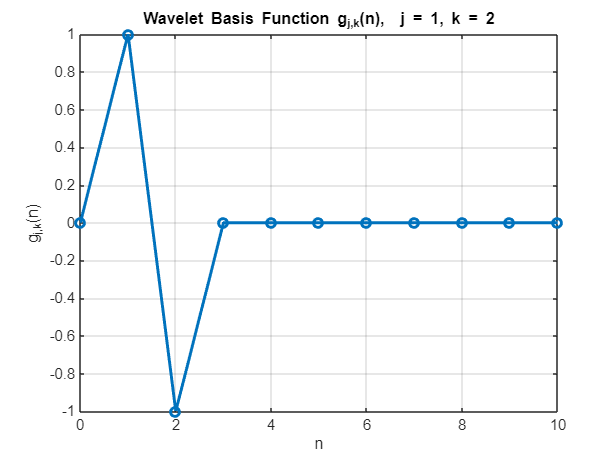

clc; clear; close all;

% Mother wavelet g(n) (from your code)
g = [1 0 -1];
% g = rand(100,1);
g = g / norm(g);

% Choose scale j and shift k (paper variables)
j = 1;        % scale
k = 2;        % shift

a = 2^j;

% Time index for plotting
n = 0:10;
% n = 0:100

% Initialize basis function
g_jk = zeros(size(n));

% Compute basis wavelet function g_{j,k}(n)
for i = 1:length(n)
    arg = a*n(i) - k;
    if arg >= 0 && arg < length(g)
        g_jk(i) = a^(1/2) * g(arg+1);
    else
        g_jk(i) = 0;
    end
end

% Plot basis wavelet function
figure;
plot(n, g_jk, '-o', 'LineWidth', 2)
title(['Wavelet Basis Function g_{j,k}(n),  j = ', num2str(j), ', k = ', num2str(k)])
xlabel('n')
ylabel('g_{j,k}(n)')
grid on

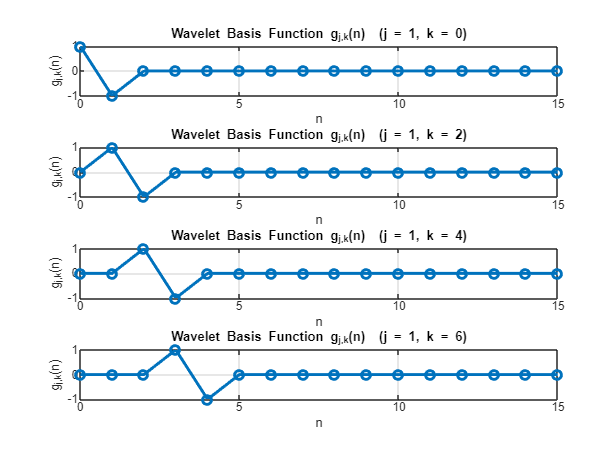

clc; clear; close all;

% Mother wavelet
g = [1 0 -1];
g = g / norm(g);

% Fixed scale j
j = 1;
a = 2^j;

% Different shifts k
k_vals = [0 2 4 6];
% 

% Time axis
n = 0:15;

figure;
for idx = 1:length(k_vals)
    k = k_vals(idx);
    g_jk = zeros(size(n));

    for i = 1:length(n)
        arg = a*n(i) - k;
        if arg >= 0 && arg < length(g)
            g_jk(i) = a^(1/2) * g(arg+1);
        end
    end

    subplot(length(k_vals),1,idx)
    plot(n, g_jk, '-o', 'LineWidth', 2)
    title(['Wavelet Basis Function g_{j,k}(n)  (j = ', num2str(j), ', k = ', num2str(k), ')'])
    xlabel('n')
    ylabel('g_{j,k}(n)')
    grid on
end

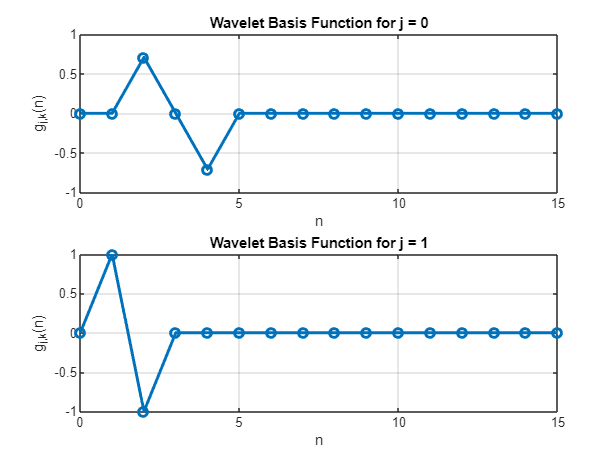

% Mother wavelet
g = [1 0 -1];
g = g / norm(g);

% Fixed shift k
k = 2;

% Different scales j
j_vals = [0 1];% Time axis
n = 0:15;

figure;hold on 
for idx = 1:length(j_vals)
    j = j_vals(idx);
    a = 2^j;

    g_jk = zeros(size(n));
    for i = 1:length(n)
        arg = a*n(i) - k;
        if arg >= 0 && arg < length(g)
            g_jk(i) = a^(1/2) * g(arg+1);
        end
    end

    subplot(length(j_vals),1,idx)
    plot(n, g_jk, '-o', 'LineWidth', 2)
    title(['Wavelet Basis Function for j = ', num2str(j)])
    xlabel('n')
    ylabel('g_{j,k}(n)')
    grid on
end